close all
clear
clc

准备工作

[t,omg,FT,IFT] = prefourier([-1.5,1.5],1000,[-12*pi,12*pi],1000);

定义原信号，计算频谱

tau = 1;
e1 = (t>-tau/2 & t<tau/2);
E1 = FT*e1;

定义理想低通滤波器1，滤波，逆变换回时域

omgc1 = 4*pi;
H1 = (omg<omgc1 & omg>-omgc1);
r11 = IFT*(E1.*H1);

定义理想低通滤波器2，滤波，逆变换回时域

omgc2 = 8*pi;
H2 = (omg<omgc2 & omg>-omgc2);
r12 = IFT*(E1.*H2);

绘图

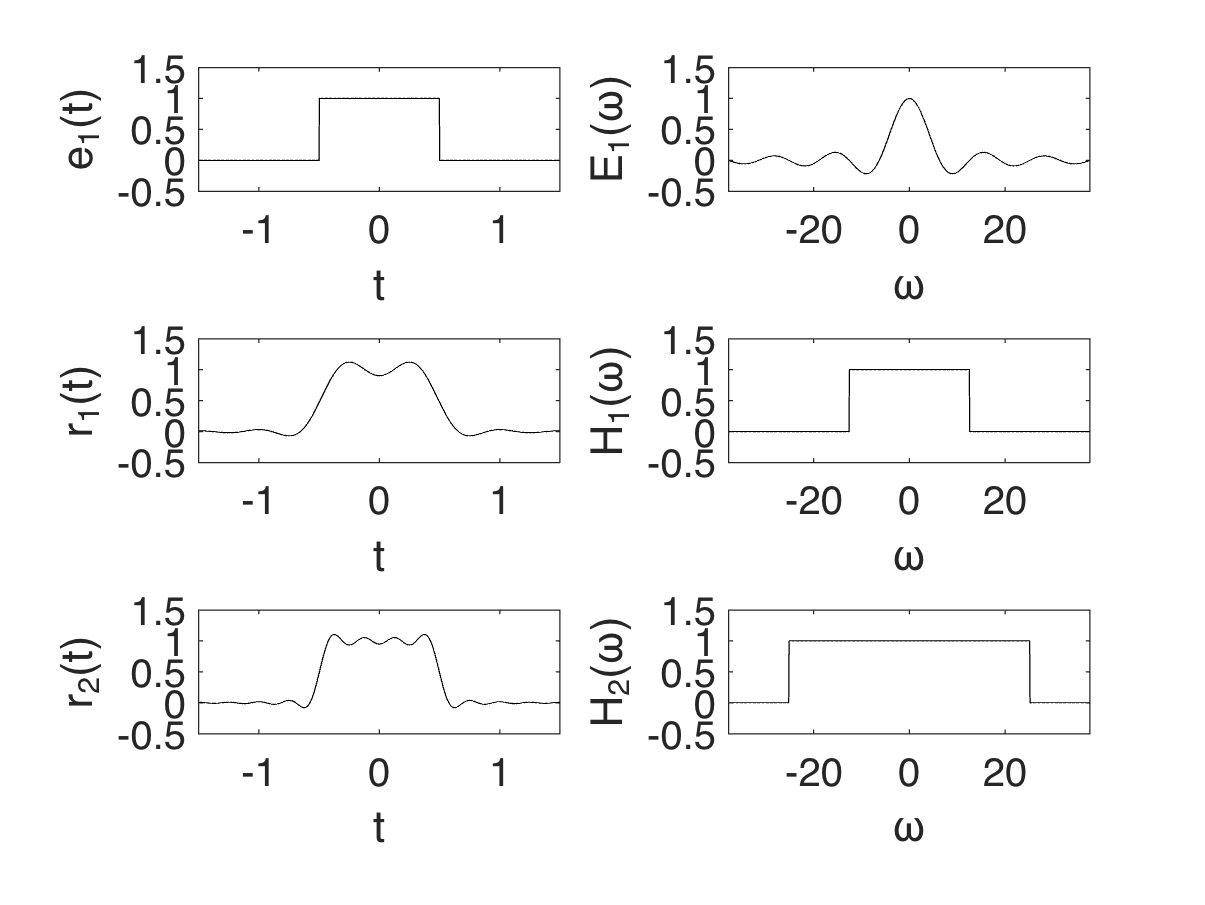

figure;
subplot(3,2,1), box on, hold on;
plot(t,e1,'k-');
set(gca,'YLim',[-0.5,1.5],'XLim',[-1.5,1.5],'FontSize',16);
xlabel('t'); ylabel('e_1(t)');

subplot(3,2,2), box on, hold on;
plot(omg,real(E1),'k-');
set(gca,'YLim',[-0.5,1.5],'XLim',[-12*pi,12*pi],'FontSize',16);
xlabel('\omega'); ylabel('E_1(\omega)');

subplot(3,2,3), hold on, box on;
plot(t,real(r11),'k-');
set(gca,'YLim',[-0.5,1.5],'XLim',[-1.5,1.5],'FontSize',16);
xlabel('t'); ylabel('r_{1}(t)');

subplot(3,2,4), hold on, box on;
plot(omg,H1,'k-');
set(gca,'YLim',[-0.5,1.5],'XLim',[-12*pi,12*pi],'FontSize',16);
xlabel('\omega'); ylabel('H_1(\omega)');

subplot(3,2,5), hold on, box on;
plot(t,real(r12),'k-');
set(gca,'YLim',[-0.5,1.5],'XLim',[-1.5,1.5],'FontSize',16);
xlabel('t'); ylabel('r_{2}(t)');

subplot(3,2,6), hold on, box on;
plot(omg,H2,'k-');
set(gca,'YLim',[-0.5,1.5],'XLim',[-12*pi,12*pi],'FontSize',16);
xlabel('\omega'); ylabel('H_2(\omega)');